clearvars
cd(fileparts(matlab.desktop.editor.getActiveFilename))
load manualSineSweep_DATA.mat;

Fs = 1800;
Ts = 1/Fs;

**Data Arrangment**

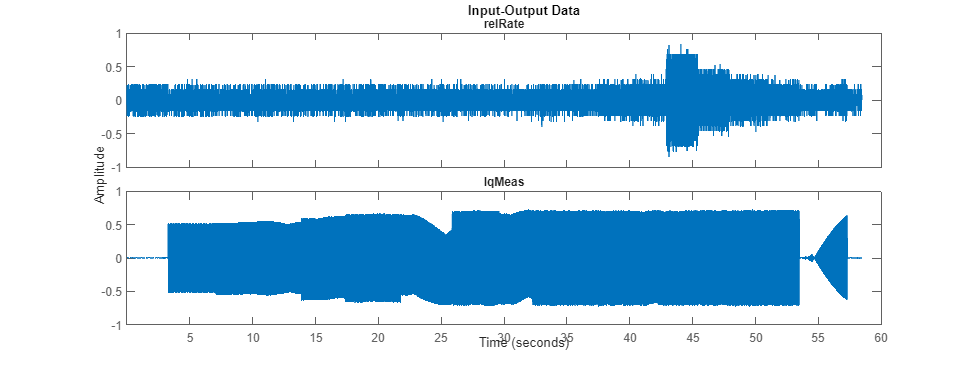

relRate = slow_data.outer_enc_der;
IqMeasAX2 = fast_data.Ax2.Iq_meas(1:2:end);

%timeDimain
I_to_W_Data = iddata(relRate, IqMeasAX2, Ts, 'Domain', 'Time', 'ExperimentName', 'Sine Manual Steps', 'InputName', 'IqMeas', 'InputUnit', {'A'}, ...
    'OutputName', 'relRate', 'OutputUnit', 'deg/s', 'TimeUnit', 'seconds');

figure('Position',[0 0 1600 600])
plot(I_to_W_Data);

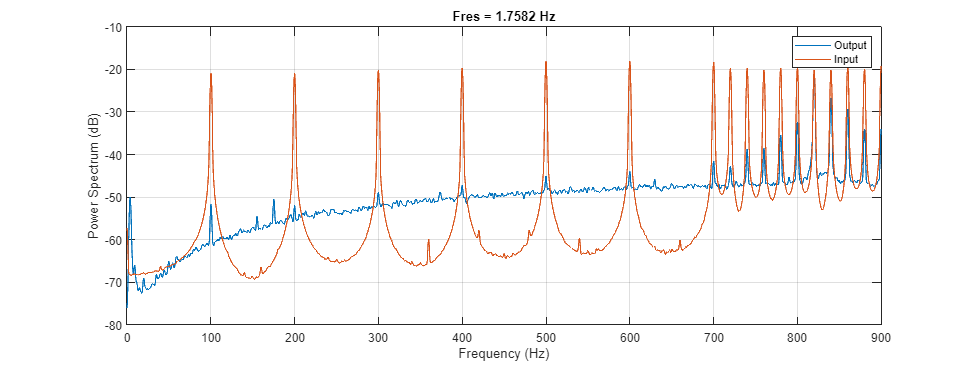

figure('Position',[0 0 1600 600])

pspectrum([I_to_W_Data.OutputData, I_to_W_Data.InputData], Fs)
legend({'Output','Input'})

num_of_delays = delayest(I_to_W_Data);
delay_time = num_of_delays*Ts;

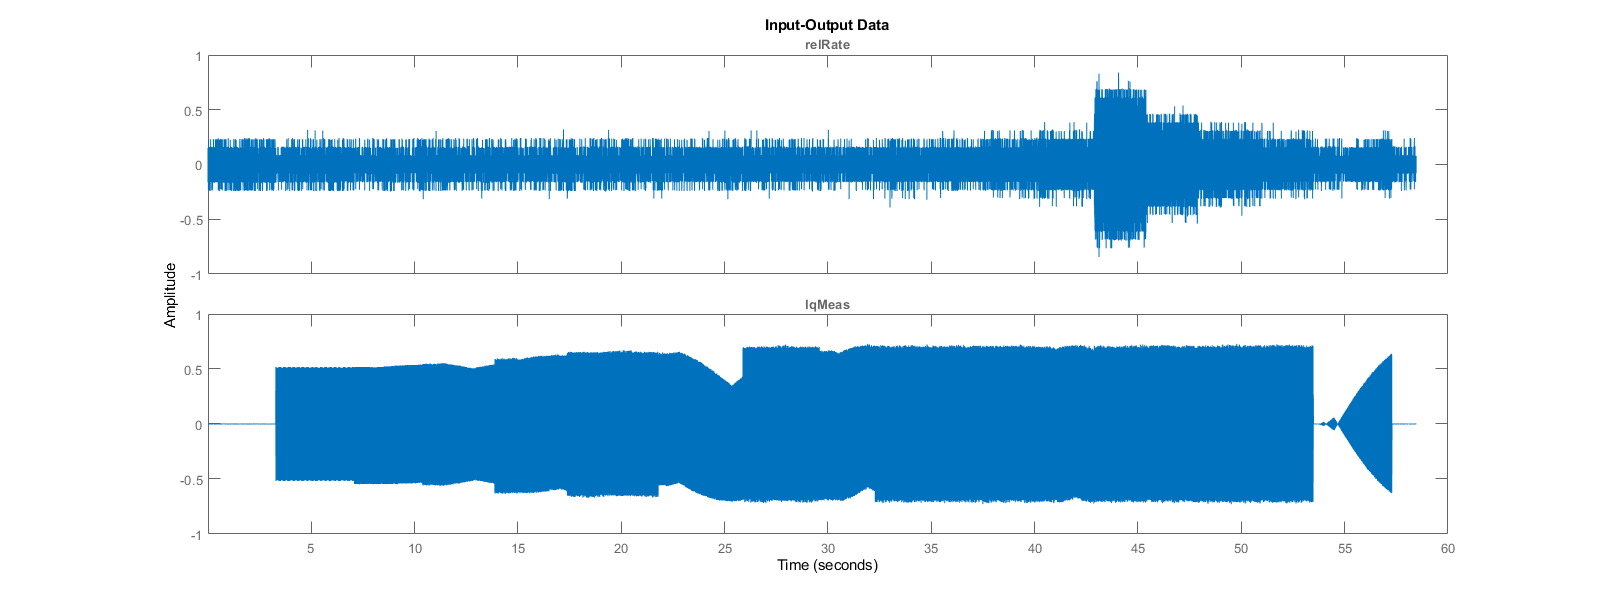

sys = tfest(I_to_W_Data, 3, 1, [])

sys =
  From input "IqMeas" to output "relRate":
            1.374e06 s + 2.799e06
  ------------------------------------------
  s^3 + 1.285e04 s^2 + 2.419e07 s + 1.465e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on time domain data "I_to_W_Data".
Fit to estimation data: 1.096%                          
FPE: 0.01786, MSE: 0.01786                              
 
Model Properties


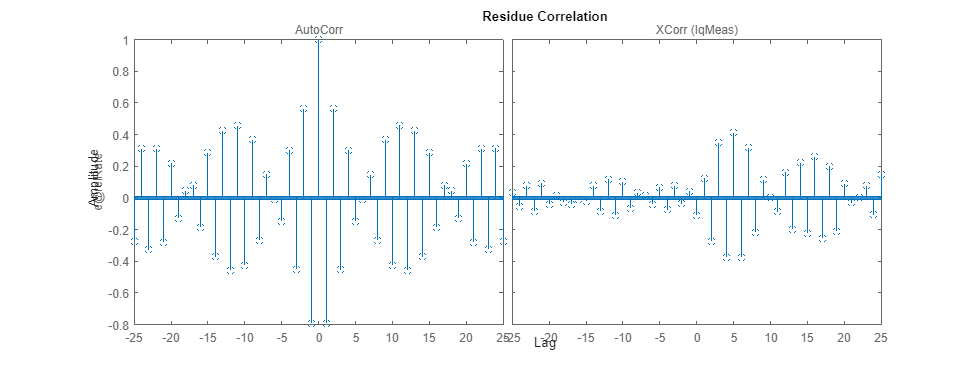

clf
resid(sys, I_to_W_Data)

sysInit = idproc('P3DU','TimeUnit','seconds');
sysOpt = procestOptions('DisturbanceModel','ARMA1');
sys1 = procest(I_to_W_Data, sysInit, sysOpt)

sys1 =
Process model with transfer function:                 
                        Kp                            
  G(s) = -------------------------------- * exp(-Td*s)
         (1+2*Zeta*Tw*s+(Tw*s)^2)(1+Tp3*s)            
                                                      
         Kp = -0.023278                               
         Tw = 0.00019487                              
       Zeta = 0.0089436                               
        Tp3 = 2.3083e-05                              
         Td = 0.00032889                              
                                                      
An additive ARMA disturbance model has been estimated 
      y = G u + (C/D)e                                
                                                      
      C(s) = s + 5.867e+04                            
      D(s) = s + 2.591e+05                            
                                                      
Parameterization:
    {'P3DU'}
   Number of free coefficie

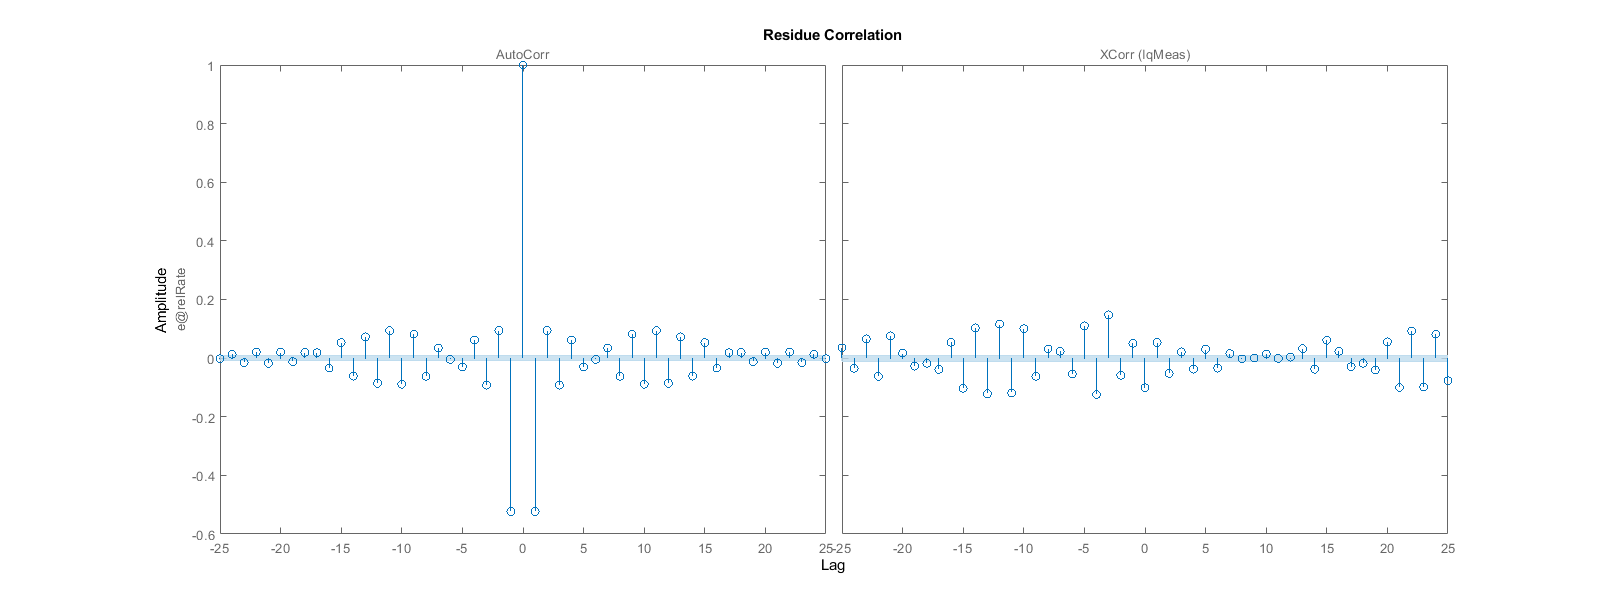

clf
resid(sys, I_to_W_Data)

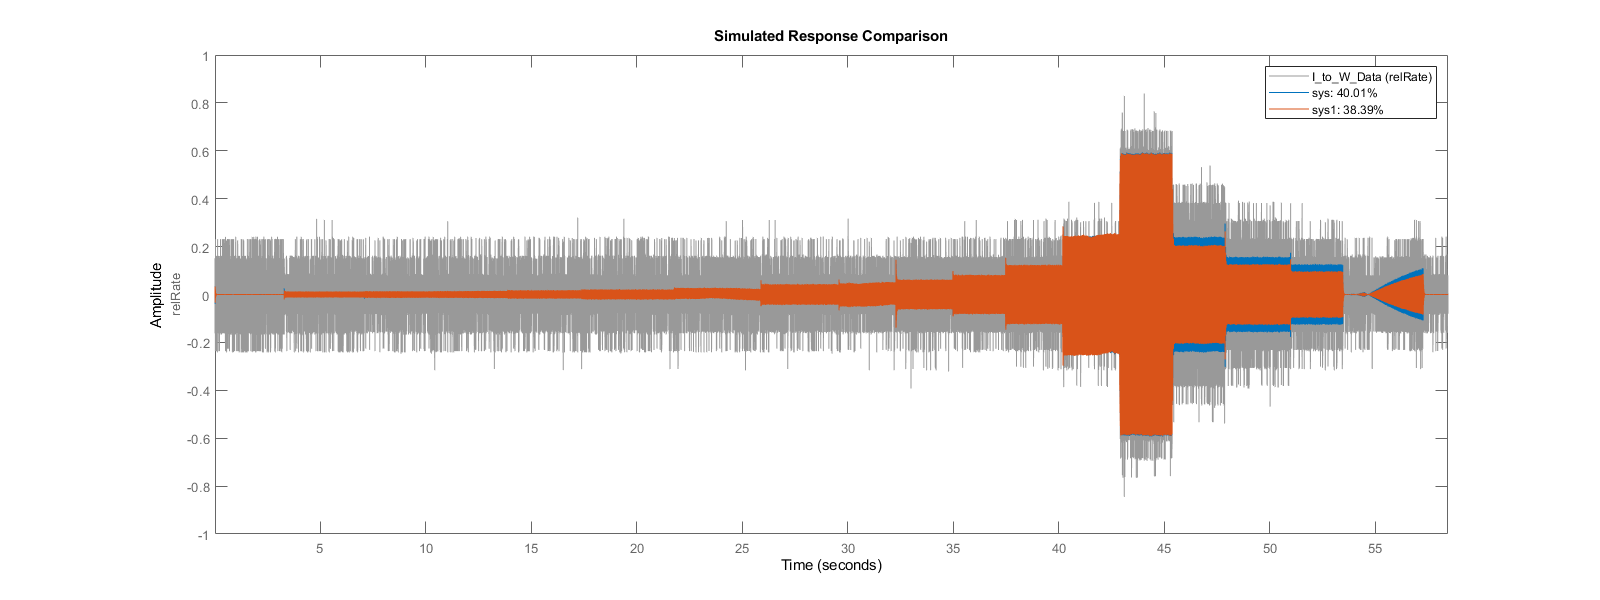

clf
compare(I_to_W_Data, sys, sys1)